Wczytanie pliku - czulosc czujnika: 100mV/g

clear;
df = readtable('pomiary.csv');
czulosc = 100; %mV/g
czuloscVnaG = czulosc*1000;
g = 9.81; %ms^-2
md = 7.4;%kg

Podzial dataframe na sygnaly

t = df(:,1); %czas
v1 = df(:, 2);% Napięcie [V] – drgania w pionie – sama rynna
v2 = df(:, 3);%Napięcie [V] – drgania w pionie – rynna z masą dodatkową md = 7,4 kg
v3 = df(:, 4);%Napięcie [V] – drgania w poziomie – sama rynna

Obciecie etykiet i kowersja do macierzy

v1 = table2array(v1(:,:));
v2 = table2array(v2(:,:));
v3 = table2array(v3(:,:));
t = table2array(t(:,:));

przeksztalcenie sygnalu z mV na m/s^2

v1 = v1./czuloscVnaG;
v2 = v2./czuloscVnaG;    %<--- sygnaly w 'g'
v3 = v3./czuloscVnaG;

v1 = g.*v1;
v2 = g.*v2;      %<--- sygnaly w ms^-2
v3 = g.*v3;

Dane o sygnalach

dt = t(2)-t(1) %krok czasowy

dt = 9.0909e-05

Fs = 1/dt      %czestotliwosc probkowania

Fs = 1.1000e+04

n = length(t)  %ilosc probek

n = 65534

f = 0:(Fs/n):(Fs/2)-(Fs/n); %wektor czestotliwosci do wykresu fft

Sygnal 1:

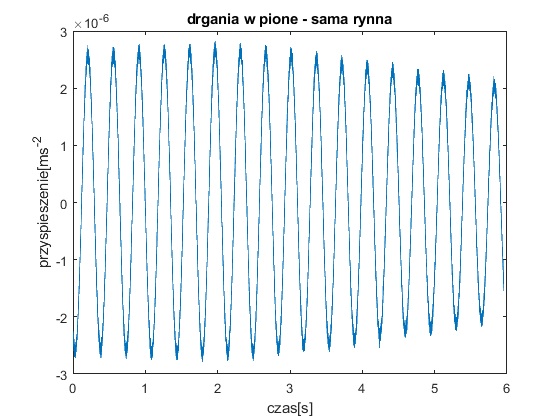

plot(t, v1);xlabel('czas[s]');ylabel('przyspieszenie[ms^{-2}');title('drgania w pione - sama rynna')

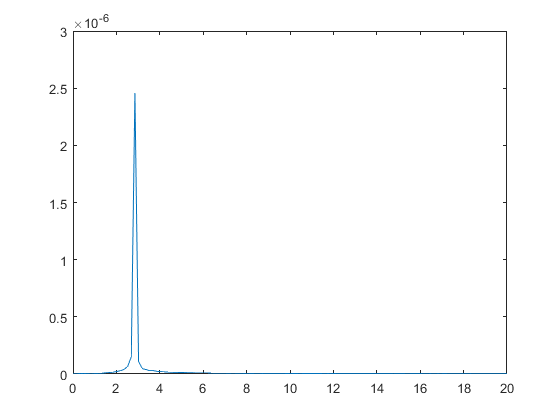


v1_fft = abs(fft(v1)./(n./2));
v1_fft = v1_fft(1:(n./2));

plot(f, v1_fft)
axis([0, 20, 0, 0.000003])

[A_V1,i_v1] = max(v1_fft);
ft_v1 = f(i_v1);
Tt_v1 = 1/ft_v1;
wt_f1 = 2*pi/Tt_v1;
fprintf('Czestotliwosc drgan wynosi %f [Hz],\n co odpowiada okresowi %f[s] i pulsacji %f[s^{-1}]',ft_v1, Tt_v1,wt_f1)

Czestotliwosc drgan wynosi 2.853480 [Hz],
 co odpowiada okresowi 0.350449[s] i pulsacji 17.928946[s^{-1}]


disp('amplituda w 3.0 sekundzie odczytana z wykresu wynosi 2.714e-6 ms^-2')

amplituda w 3.0 sekundzie odczytana z wykresu wynosi 2.714e-6 ms^-2


disp('amplituda w 5.8 sekundzie (po 8 okresach) odczytana z wykresu wynosi 2.12e-6 ms^-2')

amplituda w 5.8 sekundzie (po 8 okresach) odczytana z wykresu wynosi 2.12e-6 ms^-2


A_v1_3s = 2.714e-6;
A_v1_6s = 2.12e-6;
d_v1 = log(A_v1_3s/A_v1_6s);
beta_v1 = d_v1/8*Tt_v1;
fprintf('Logarytmiczny dekrement tlumienia wynosi %f', d_v1)

Logarytmiczny dekrement tlumienia wynosi 0.247007

fprintf('Wspolczynnik tlumienia beta wynosi %f,', beta_v1)

Wspolczynnik tlumienia beta wynosi 0.010820,

Sygnal 2 - z obciazeniem dodatkowym

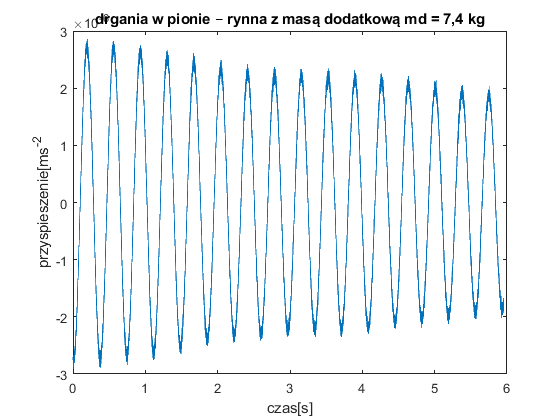

plot(t, v2);xlabel('czas[s]');ylabel('przyspieszenie[ms^{-2}');title('drgania w pionie – rynna z masą dodatkową md = 7,4 kg')

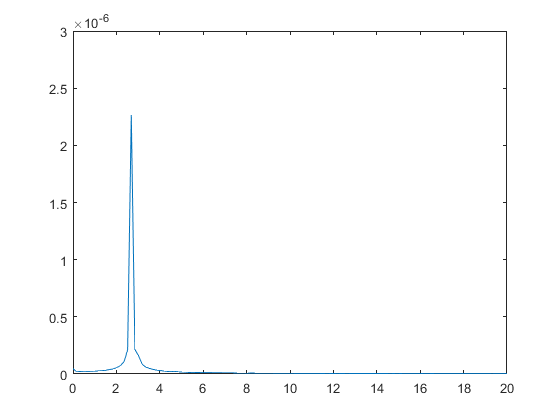


v2_fft = abs(fft(v2)./(n./2));
v2_fft = v2_fft(1:(n./2));
plot(f, v2_fft)
axis([0, 20, 0, 0.000003])

[A_V2,i_v2] = max(v2_fft);
ft_v2 = f(i_v2);
Tt_v2 = 1/ft_v2;
wt_f2 = 2*pi/Tt_v2;
fprintf('Czestotliwosc drgan dla sygnalu 2 wynosi %f [Hz],\n co odpowiada okresowi %f[s] i pulsacji %f[s^{-1}]',ft_v2, Tt_v2,wt_f2)

Czestotliwosc drgan dla sygnalu 2 wynosi 2.685629 [Hz],
 co odpowiada okresowi 0.372352[s] i pulsacji 16.874302[s^{-1}]

disp('amplituda w 2.7 sekundzie odczytana z wykresu wynosi 2.745e-6 ms^-2')

amplituda w 2.7 sekundzie odczytana z wykresu wynosi 2.745e-6 ms^-2


disp('amplituda w 4.6 sekundzie (po 10 okresach) odczytana z wykresu wynosi 2.188e-6 ms^-2')

amplituda w 4.6 sekundzie (po 10 okresach) odczytana z wykresu wynosi 2.188e-6 ms^-2


A_v2_2s = 2.745e-6;
A_v2_4s = 2.188e-6;
d_v2 = log(A_v2_2s/A_v2_4s)

d_v2 = 0.2268

beta_v2 = d_v2/10*Tt_v2;
fprintf('Logarytmiczny dekrement tlumienia wynosi %f', d_v2)

Logarytmiczny dekrement tlumienia wynosi 0.226793

fprintf('Wspolczynnik tlumienia beta wynosi %f,', beta_v2)

Wspolczynnik tlumienia beta wynosi 0.008445,

Obliczanie wspolczynnikow sprezystosci i tlumienia

syms kz bz m
eqns = [beta_v1^2*2*m == beta_v2^2*(2*m+2*md)];
    [m] = solve(eqns)

$$m = \frac{19469265324859173}{1688584615483985}$$

disp('masa przenosnika bez mas niewywazonych wynosi')

masa przenosnika bez mas niewywazonych wynosi


   m = double(m)

m = 11.5299

disp('wspolczynnik tlumienia bz wynosi')

wspolczynnik tlumienia bz wynosi


bz = beta_v1^2*2*m

bz = 0.0027

disp('wspolczynnik sprezystosci kz wynosi')

wspolczynnik sprezystosci kz wynosi


kz = m*(wt_f1^2+beta_v1^2)

kz = 3.7063e+03

Sygnal 3 - os x

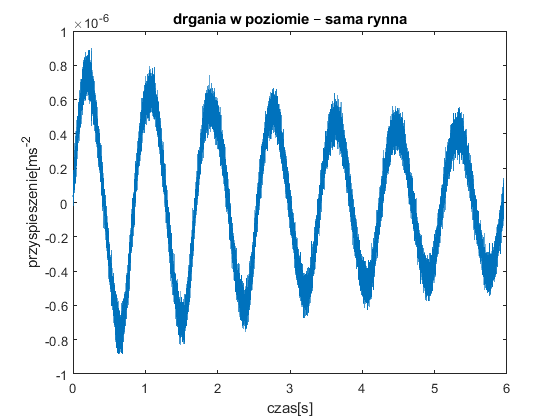

plot(t, v3);xlabel('czas[s]');ylabel('przyspieszenie[ms^{-2}');title('drgania w poziomie – sama rynna')

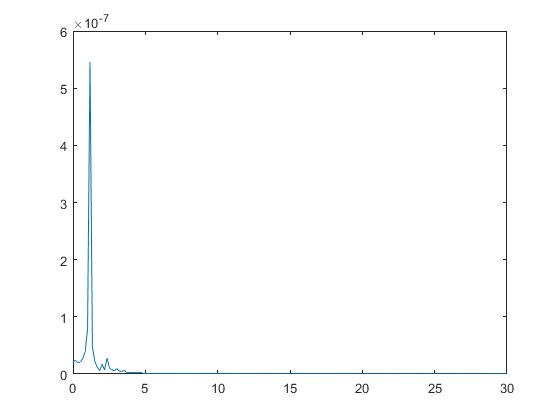


v3_fft = abs(fft(v3)./(n./2));
v3_fft = v3_fft(1:(n./2));

plot(f, v3_fft)
axis([0, 30, 0, 0.0000006])

[A_V1,i_v3] = max(v3_fft);
ft_v3 = f(i_v3);
Tt_v3 = 1/ft_v3;
wt_f3 = 2*pi/Tt_v3;
fprintf('Czestotliwosc drgan wynosi %f [Hz],\n co odpowiada okresowi %f[s] i pulsacji %f[s^{-1}]',ft_v3, Tt_v3,wt_f3)

Czestotliwosc drgan wynosi 1.174962 [Hz],
 co odpowiada okresowi 0.851091[s] i pulsacji 7.382507[s^{-1}]

disp('amplituda w 0.2 sekundzie odczytana z wykresu wynosi 7.456e-7 ms^-2')

amplituda w 0.2 sekundzie odczytana z wykresu wynosi 7.456e-7 ms^-2


disp('amplituda w 5.3 sekundzie (po 6 okresach) odczytana z wykresu wynosi 3.997e-7 ms^-2')

amplituda w 5.3 sekundzie (po 6 okresach) odczytana z wykresu wynosi 3.997e-7 ms^-2


A_v3_1s = 2.745e-6;
A_v3_5s = 2.188e-6;
d_v3 = log(A_v3_1s/A_v3_5s)

d_v3 = 0.2268

beta_v3 = d_v3/6*Tt_v3;
fprintf('Logarytmiczny dekrement tlumienia wynosi %f', d_v3)

Logarytmiczny dekrement tlumienia wynosi 0.226793

fprintf('Wspolczynnik tlumienia beta wynosi %f,', beta_v3)

Wspolczynnik tlumienia beta wynosi 0.032170,


disp('Wspolczynnik tlumienia bx wynosi')

Wspolczynnik tlumienia bx wynosi


bx = beta_v3^2*2*m

bx = 0.0239

disp('wspolczynnik sprezystosci kx wynosi')

wspolczynnik sprezystosci kx wynosi


kx = m*(wt_f3^2+beta_v3^2)

kx = 628.4095